   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e-04

   2.0000e

new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy run
new energy

U_old = -2.0231e-42

U_new = -6.4511e-42

e_old = 1

e_new = 1

val = 1

here


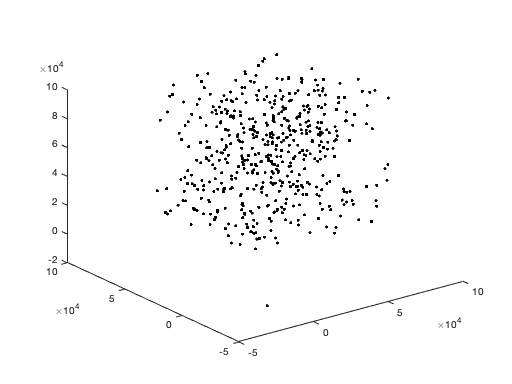

%%% Question 1 %%%%
N = 500; rho_1 = 0.6;                                  % Particles, density
sigma = 0.0001; R = 2*sigma; epsilon = 1;                    % Cutoff distance, cutoff (particle radius), well depth
L = (N/rho_1)^(1/3);                                  % length
Lred = L/sigma;                 % Just messing with this value at this point
% Cutoff is temporary; technically not needed except for first iteration
% (will need to change)
T = 0.9; iterations =1;                            % Setting iterations as 100 times for now    
Kb = 1.38064852 * 10^-23;                               % m2 kg s-2 K-1 
global B; B = epsilon;   %1/(Kb*T);                  % Not working?               % Repeat in each section?

[pos_hist, P_hist, vir_hist, U_hist] = MC_Project_Pipeline(N, R, Lred, T, sigma, epsilon, iterations, rho_1);

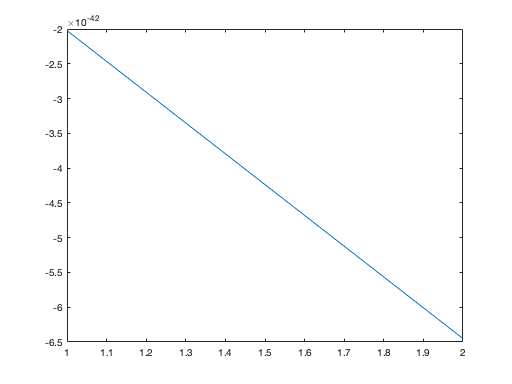


plot(U_hist); 

% %%% Question 2 %%%
% rho_2 = 0.1:0.1:1;
% T_2 = [2,0.9];
% % for i = 1:length(T_2)
%    % T = T_2(i)
%     P_rho = [];
%     for j = 1:length(rho_2)
%         rho = rho_2(j)
%         [pos_hist, P_hist, vir_hist, U_hist] = MC_Project_Pipeline(N, R, L, T, sigma, epsilon, iterations, rho);
%         P_avg = mean(P_hist); 
%         P_rho = [P_rho, P_avg];
%         %run monte carlo code, extract P(rho) and store in a matrix  
%         j = j+1
%     end
%     %store matrix from inner for loop as variable for that temperature
%     %(should end up with two)
%     subplot(1, 2, i); 
%     plot(rho_2, P_rho); 
% %     i = i+1
% % end
% % plot P(rho) for T_2[1]
% % plot P(rho) for T_2[2]
% %answer: for which densities and temperatures you observe phase separation?

%%% Question 3 %%%
% snapshots showing phase separation, liquid, gas (x3)

%%% Question 4 %%%
% up to what density is ideal gas good approx.?

%%% Question 5 %%%
% gaussian displacement instead of uniform

%%% Question 6 %%%
% displace all particles every move, max displacement where 50% accepted